clearvars
format long

# Research Techniques Project: Unit test

This is a unit test using the KIC 11924311 source since it has documented periodicity

## Data Exploration

In this section we are exploring and displaying the raw data so it can be used for analysis

opts = detectImportOptions("KIC_11924311_Photometry.txt");
opts.DataLines = 2;
%opts.VariableNames = {'B_time','B_flux','R_time','R_flux','V_time','V_flux'};
opts.VariableNames = {'Time','Filter','Flux','error'};

"time" is in the units of days and "flux" is "rel_flux_T1" from AstroImageJ outputs. 

opts.VariableTypes = {'double','char','double','double'};

ans = 8×4 table
    Time     Filter     Flux       error  
    _____    ______    _______    ________

    57985    {'B'}     0.67636    0.002971
    57985    {'B'}      0.6859       0.003
    57985    {'B'}     0.68148    0.002991
    57985    {'B'}     0.69522    0.003017
    57985    {'B'}     0.69789    0.003033
    57985    {'B'}     0.69235    0.003006
    57985    {'B'}     0.70017    0.003037
    57985    {'B'}     0.69389    0.002996


KIC_11924311 = rmmissing(readtable("KIC_11924311_Photometry.txt",opts)); %the matrix data of the text file

  Name                 Size             Bytes  Class    Attributes

  KIC_11924311      2957x4             386047  table              



preview("KIC_11924311_Photometry.txt",opts)
whos KIC_11924311
filters = unique(KIC_11924311{:,2},'stable');
poscount = [1 0 0 0 0];
temp = zeros(1,4);
 
count = 1;
poscount(count+1) = poscount(count);
while char(filters(count))==char(KIC_11924311{poscount(count+1),2}) 
    poscount(count+1) = poscount(count+1) + 1;

KICB = 349×4 table
    Time     Filter     Flux       error  
    _____    ______    _______    ________

    57985    {'B'}     0.67636    0.002971
    57985    {'B'}      0.6859       0.003
    57985    {'B'}     0.68148    0.002991
    57985    {'B'}     0.69522    0.003017
    57985    {'B'}     0.69789    0.003033
    57985    {'B'}     0.69235    0.003006
    57985    {'B'}     0.70017    0.003037
    57985    {'B'}     0.69389    0.002996
    57985    {'B'}     0.70967    0.003057
    57985    {'B'}     0.70263    0.003026
    57985    {'B'}     0.70944    0.003056
    57985    {'B'}     0.71281    0.003053
    57985    {'B'}     0.71539    0.003062
    57985    {'B'}     0.71921    0.003146
    57985    {'B'}     0.72563    0.003272
    57985    {'B'}     0.72387    0.003132


end
KICB = KIC_11924311(poscount(count):poscount(count+1)-1,:)
count = 2;
poscount(count+1) = poscount(count);
while char(filters(count))==char(KIC_11924311{poscount(count+1),2}) 
    poscount(count+1) = poscount(count+1) + 1;

KICV = 350×4 table
    Time     Filter     Flux       error  
    _____    ______    _______    ________

    57985    {'V'}     0.72608     0.00284
    57985    {'V'}     0.72676    0.002841
    57985    {'V'}     0.72877    0.002839
    57985    {'V'}     0.73102    0.002843
    57985    {'V'}     0.73477    0.002852
    57985    {'V'}     0.74009    0.002877
    57985    {'V'}     0.74063    0.002859
    57985    {'V'}     0.74478    0.002875
    57985    {'V'}     0.74259    0.002859
    57985    {'V'}     0.74714    0.002874
    57985    {'V'}     0.74956     0.00288
    57985    {'V'}     0.75451    0.002899
    57985    {'V'}     0.76023    0.002918
    57985    {'V'}     0.76028     0.00292
    57985    {'V'}     0.75968    0.002942
    57985    {'V'}     0.76063    0.003006


end
KICV = KIC_11924311(poscount(count):poscount(count+1)-1,:)
count = 3;
poscount(count+1) = poscount(count);
while char(filters(count))==char(KIC_11924311{poscount(count+1),2}) 
    poscount(count+1) = poscount(count+1) + 1;

KICR = 350×4 table
    Time     Filter     Flux       error  
    _____    ______    _______    ________

    57985    {'R'}     0.74284    0.003048
    57985    {'R'}     0.74456    0.003066
    57985    {'R'}     0.75455     0.00309
    57985    {'R'}     0.75485    0.003076
    57985    {'R'}     0.75807    0.003077
    57985    {'R'}     0.76211    0.003086
    57985    {'R'}     0.76861     0.00311
    57985    {'R'}      0.7702    0.003132
    57985    {'R'}     0.76533    0.003096
    57985    {'R'}     0.76892    0.003097
    57985    {'R'}      0.7678     0.00309
    57985    {'R'}     0.77622     0.00313
    57985    {'R'}     0.78119    0.003148
    57985    {'R'}     0.78604    0.003168
    57985    {'R'}      0.7865    0.003223
    57985    {'R'}     0.79157    0.003204


end
KICR = KIC_11924311(poscount(count):poscount(count+1)-1,:)
count = 4;
poscount(count+1) = poscount(count);
while char(filters(count))==char(KIC_11924311{poscount(count+1),2}) 
    poscount(count+1) = poscount(count+1) + 1;

KICI = 350×4 table
    Time     Filter     Flux       error  
    _____    ______    _______    ________

    57985    {'I'}     0.76493    0.005148
    57985    {'I'}     0.78074    0.005261
    57985    {'I'}      0.7751    0.005121
    57985    {'I'}     0.77435    0.005184
    57985    {'I'}     0.78234    0.005198
    57985    {'I'}     0.78959    0.005184
    57985    {'I'}     0.78702    0.005132
    57985    {'I'}     0.78799    0.005191
    57985    {'I'}     0.79257    0.005159
    57985    {'I'}     0.79262    0.005145
    57985    {'I'}     0.79892    0.005188
    57985    {'I'}     0.80309    0.005174
    57985    {'I'}     0.81054    0.005176
    57985    {'I'}     0.80187     0.00522
    57985    {'I'}     0.80033     0.00521
    57985    {'I'}     0.80613    0.005146


end
KICI = KIC_11924311(poscount(count):poscount(count+1)-1,:)

To understand the nature of the data, it is important to visualise it. This example is from the B filter. Error is ignored for the analysis in this project.

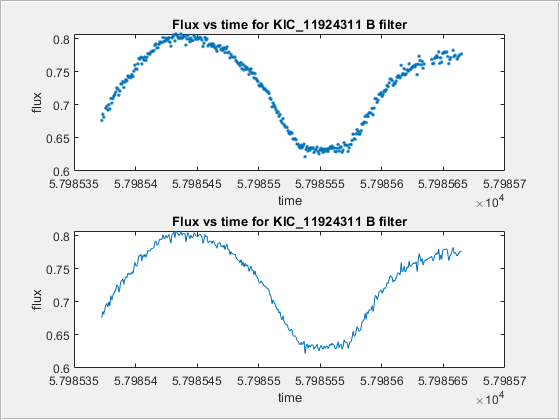

hf_sub(1) = figure(1);
hp(1) = uipanel('Parent',hf_sub(1),'Position',[0 0 1 1]);
subplot(2,1,1,'Parent',hp(1));
plot(KICB.Time,KICB.Flux,'.')
title('Flux vs time for KIC\_11924311 B filter');
xlabel('time'),ylabel('flux');
subplot(2,1,2,'Parent',hp(1));
plot(KICB.Time,KICB.Flux),title('Flux vs time for KIC\_11924311 B filter')
xlabel('time');

ylabel('flux');

Noting the graph above - displayed in discrete points and as a line graph - there is some periodicity.

r = abs([0; KICB.Time] - [KICB.Time;0]);
round(mean(r(3:end-1)),8)

ans = 8.3931e-04

## Periodicity between filters

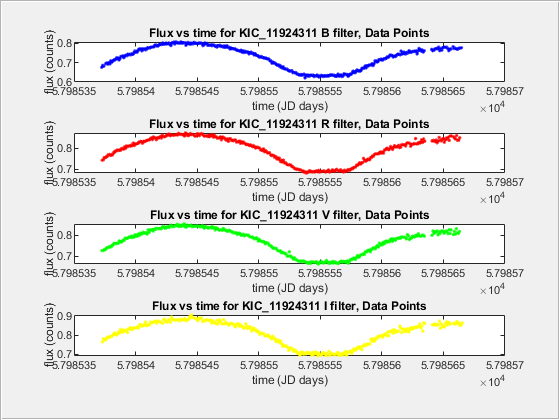

hf_sub(2) = figure(2);
hp(2) = uipanel('Parent',hf_sub(2),'Position',[0 0 1 1]);
subplot(4,1,1,'Parent',hp(2));
% plotting in blue because B filter is blue light (~400-500 nm)
plot(KICB.Time,KICB.Flux,'.b')
title('Flux vs time for KIC\_11924311 B filter, Data Points');
xlabel('time (JD days)');
ylabel('flux (counts)');
subplot(4,1,2,'Parent',hp(2));
% plotting in red because R filter is red light (~550-800 nm)
plot(KICR.Time,KICR.Flux,'.r');
title('Flux vs time for KIC\_11924311 R filter, Data Points');
xlabel('time (JD days)');
ylabel('flux (counts)');
subplot(4,1,3,'Parent',hp(2));
% plotting green but V filter is visible light (~500-700 nm)
plot(KICV.Time,KICV.Flux,'.g');
title('Flux vs time for KIC\_11924311 V filter, Data Points');
xlabel('time (JD days)');
ylabel('flux (counts)');
subplot(4,1,4,'Parent',hp(2));
% plotting green but I filter is visible light (~500-700 nm)
plot(KICI.Time,KICI.Flux,'.y');
title('Flux vs time for KIC\_11924311 I filter, Data Points');
xlabel('time (JD days)');
ylabel('flux (counts)');

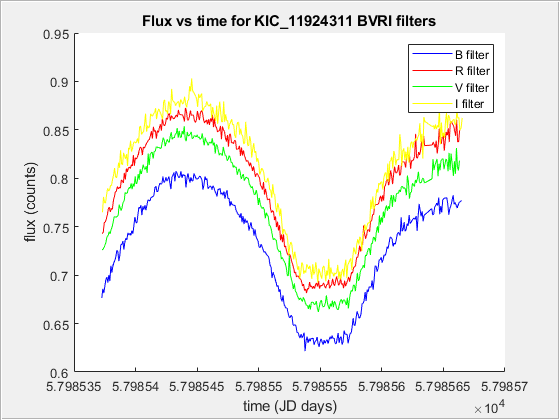


hf_sub(3) = figure(3);
hp(3) = uipanel('Parent',hf_sub(3),'Position',[0 0 1 1]);
subplot(1,1,1,'Parent',hp(3))
hold on
plot(KICB.Time,KICB.Flux, 'b')
plot(KICR.Time,KICR.Flux, 'r')
plot(KICV.Time,KICV.Flux, 'g')
plot(KICI.Time,KICI.Flux, 'y')
hold off
title('Flux vs time for KIC\_11924311 BVRI filters');
xlabel('time (JD days)');
legend('B filter', 'R filter', 'V filter', 'I filter');
ylabel('flux (counts)');

## Interpolation investigation

Custom linear function interpolation is shown here. Polyfit was a poor approximation but nearest or spline could also be used - check progress work.

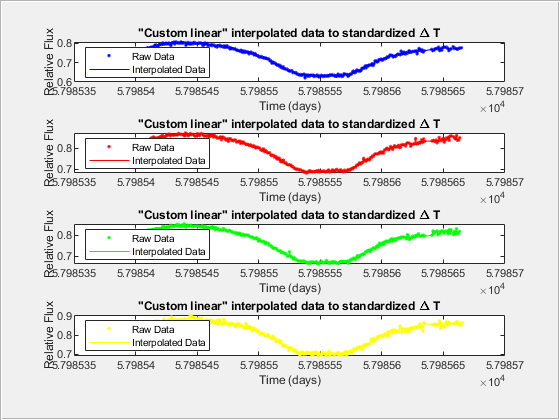

hf_sub(4) = figure(4);
hp(4) = uipanel('Parent',hf_sub(4),'Position',[0 0 1 1]);
subplot(4,1,1,'Parent',hp(4));
[Tnew,Mnew] = Interp_Lin(KICB.Time,KICB.Flux);
plot(KICB.Time,KICB.Flux,'.b',Tnew,Mnew,'b');
title('"Custom linear" interpolated data to standardized \Delta T');
legend('Raw Data','Interpolated Data','location','northwest');
xlabel('Time (days)');
ylabel('Relative Flux');
subplot(4,1,2,'Parent',hp(4));
[Tnew,Mnew] = Interp_Lin(KICR.Time,KICR.Flux);
plot(KICR.Time,KICR.Flux,'.r',Tnew,Mnew,'r');
title('"Custom linear" interpolated data to standardized \Delta T');
legend('Raw Data','Interpolated Data','location','northwest');
xlabel('Time (days)');
ylabel('Relative Flux');
subplot(4,1,3,'Parent',hp(4));
[Tnew,Mnew] = Interp_Lin(KICV.Time,KICV.Flux);
plot(KICV.Time,KICV.Flux,'.g',Tnew,Mnew,'g');
title('"Custom linear" interpolated data to standardized \Delta T');
legend('Raw Data','Interpolated Data','location','northwest');
xlabel('Time (days)');
ylabel('Relative Flux');
subplot(4,1,4,'Parent',hp(4));
[Tnew,Mnew] = Interp_Lin(KICI.Time,KICI.Flux);
plot(KICI.Time,KICI.Flux,'.y',Tnew,Mnew,'y');
title('"Custom linear" interpolated data to standardized \Delta T');
legend('Raw Data','Interpolated Data','location','northwest');
xlabel('Time (days)');
ylabel('Relative Flux');

## Fourier transform

This is the source for implementing Fourier Transform for a Noisy Signal from the MathWorks documentation

We chose linear interpolation for the purposes of this experiment at random.

Documentation:  We used a combination of the following sources to develop this:

- [https://www.mathworks.com/help/matlab/ref/fft.html?searchHighlight=fft&s_tid=srchtitle](https://www.mathworks.com/help/matlab/ref/fft.html?searchHighlight=fft&s_tid=srchtitle) (This is the source for implementing Fourier Transform for a Noisy Signal from the MathWorks documentation)

- Gilat, Example 7-6 (pg. 281)

- Gilat, Example 7-8 (pg 287)

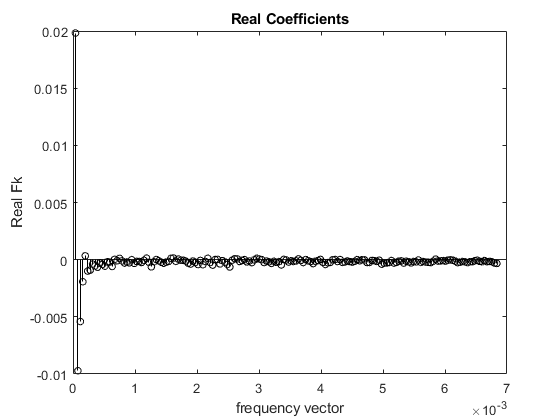

[Tnew,Mnew] = Interp_Lin(KICB.Time,KICB.Flux);
Tnew = Tnew*86400; %convert time from days to seconds
deltaT = Tnew(2)-Tnew(1);
Fs = 1/deltaT;           % Sampling frequency
T = deltaT;             % Sampling period
t = Tnew-Tnew(1);                % Time vector
L = numel(Tnew);         % Length of signal
X = Mnew ;              %signal with noise



%Fourier transformation    %Based on Ex 7-6 Gilat
F = fft(X)/L  ;            %fourier transform devided by number of data points
power = F.*conj(F)/L;
powernorm = power/max(power);   %normalized power spectrum
fk = (0:L-1)*(Fs/L);      %frequency vector Gilat 7-6
stem(fk(2:floor(L/2)),real(F(2:floor(L/2))), 'ko','markersize',5)             %Threw out first number of F because seemingly significant outlier
xlabel('frequency vector')
ylabel('Real Fk')
title('Real Coefficients')

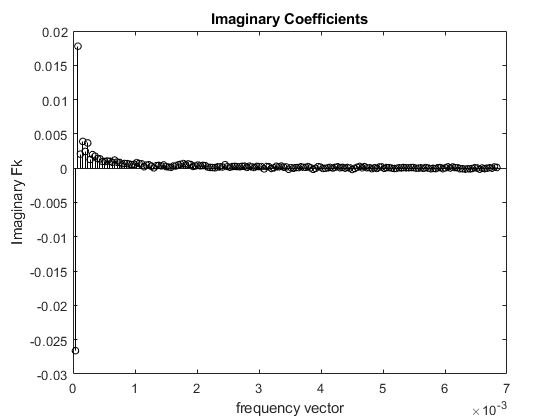

figure, stem(fk(2:floor(L/2)),imag(F(2:floor(L/2))),'ko','markersize',5)
xlabel('frequency vector')
ylabel('Imaginary Fk')
title('Imaginary Coefficients')

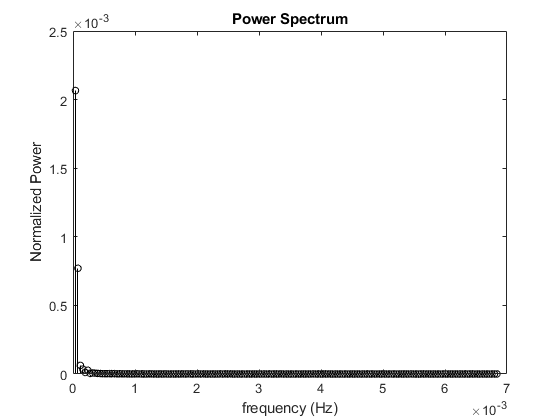

figure, stem(fk(2:floor(L/2)),powernorm(2:floor(L/2)),'ko','markersize',5)
xlabel('frequency (Hz)')
ylabel('Normalized Power')
title('Power Spectrum')

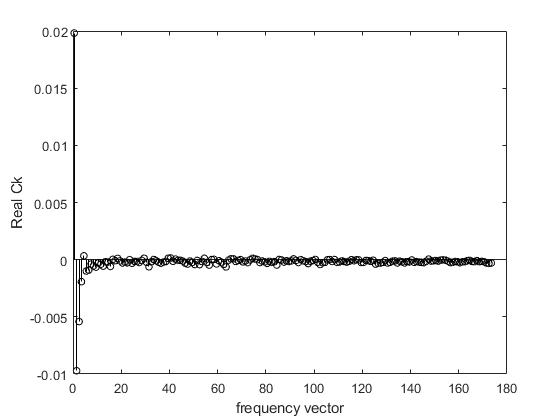


%Rearrange the spectrum using fftshift
C0 = fftshift(F(2:L));              %zero frequency in center (threw out first number of F as an outlier)
power0 = C0.*conj(C0)/L-1;
powernorm0 = power0/max(power0);   %normalized power spectrum
fk0 = (-L/2+1:L/2-1)*(Fs/L-1);      %frequency vector Gilat 7-6
stem(fk0(1:floor(L/2)),real(C0(1:floor(L/2))), 'ko','markersize',5)
xlabel('frequency vector')
ylabel('Real Ck')

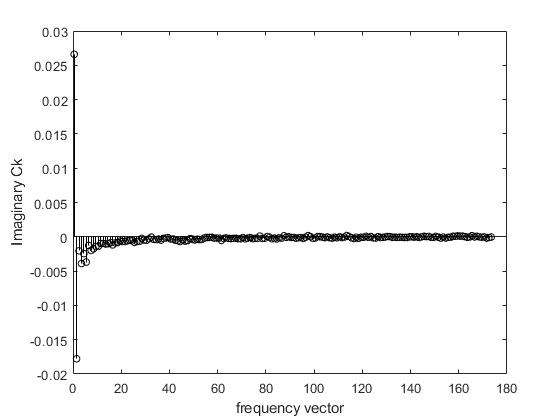

figure, stem(fk0(1:floor(L/2)),imag(C0(1:floor(L/2))),'ko','markersize',5)
xlabel('frequency vector')
ylabel('Imaginary Ck')

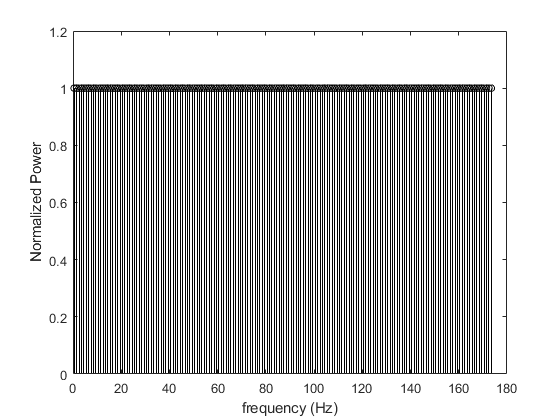

figure, stem(fk0(1:floor(L/2)),powernorm0(1:floor(L/2)),'ko','markersize',5)
xlabel('frequency (Hz)')
ylabel('Normalized Power')

This approach has failed because their appears to not be much noise in the original source which has lead to a difficulty to remove noise.

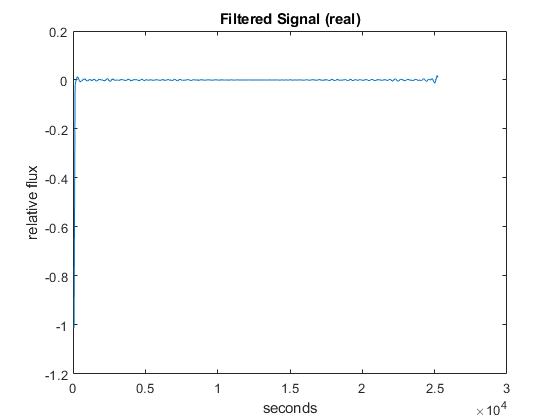

%Filtering out the noise            Based on Gilat Example 7-8

for k = 1:L-1
    if abs(fk0(k)) <= 50 || abs(fk0(k)) >= 90
        C0flter(k) = 0+0i;
    
    else
        C0flter(k) = C0(k);
    end
end


F0i = ifftshift(C0flter) * L-1;
finv = ifft(F0i);
figure, plot(t(2:L),real(finv))
title('Filtered Signal (real)')
xlabel('seconds')
ylabel('relative flux')

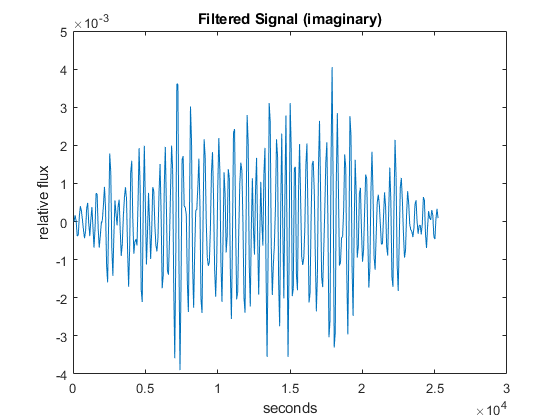

F0i = ifftshift(C0flter) * L-1;
finv = ifft(F0i);
figure, plot(t(2:L),imag(finv))
title('Filtered Signal (imaginary)')
xlabel('seconds')
ylabel('relative flux')

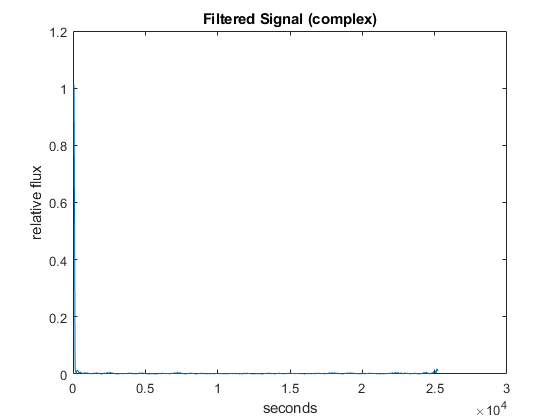

F0i = ifftshift(C0flter) * L-1;
finv = ifft(F0i);
figure, plot(t(2:L),abs(finv))
title('Filtered Signal (complex)')
xlabel('seconds')
ylabel('relative flux')

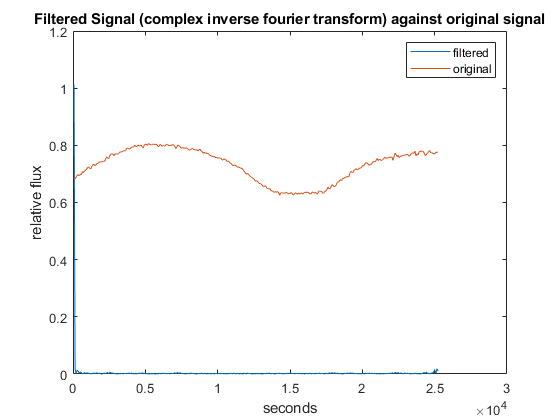

F0i = ifftshift(C0flter) * L-1;
finv = ifft(F0i);
figure, plot(t(2:L),abs(finv),t(2:L),X(2:L))
legend('filtered','original')
title('Filtered Signal (complex inverse fourier transform) against original signal')
xlabel('seconds')
ylabel('relative flux')

This approach failed for this star because the signal was read as noise.

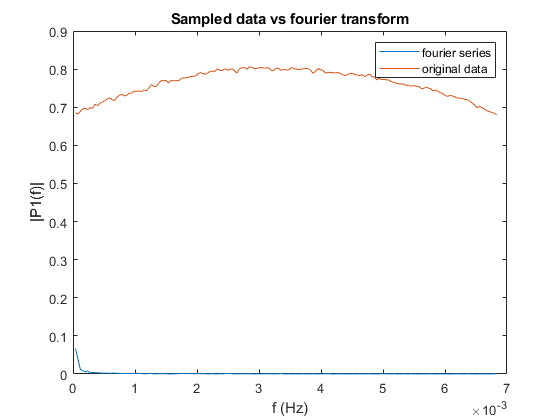

F =1./t(2:L);

%Fourier transformation
Y = fft(X);
P2complex = abs(Y/L); %real and imaginary parts together
P2real = 2*real(Y);
P2imaginary = 2*imag(Y);
P1complex = P2complex(1:floor(L/2)+1);
P1complex(2:end-1) = 2*P1complex(2:end-1);

%Plot

f = Fs*(0:(L/2))/L;
plot(f(2:end-1),P1complex(2:end-1),f(2:end-1),X(2:floor(L/2)))
title('Sampled data vs fourier transform')
xlabel('f (Hz)')
ylabel('|P1(f)|')
legend('fourier series','original data')

## Identify key frequencies

Use Linear Interpolation, then use a Fourier transform to attain the power spectrum

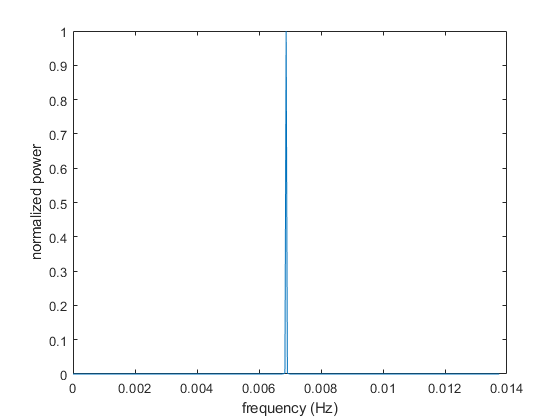

fk =          0    0.0000    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0010    0.0010    0.0011    0.0011    0.0011    0.0012    0.0012    0.0013    0.0013    0.0013    0.0014    0.0014    0.0015    0.0015    0.0015    0.0016    0.0016    0.0017    0.0017    0.0017    0.0018    0.0018    0.0019    0.0019    0.0019


powerNor =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


[Tnew,Mnew] = Interp_Lin(KICB.Time,KICB.Flux);  
Tnews = Tnew*86400; %convert time from days to seconds
dt = Tnews(2) - Tnews(1);
[fk,powerNor] = EnergySpec(Tnews,Mnew,dt)

0.006876 Hz is the frequency of the peak.

0.006876*3600*24

ans = 594.0864

Therefore 594.0864 per day

## Linear Combination of non-linear functions

## Guess 1: Linear functions with original data

F1 =  @(x) x./x;
F2 =  @(x) cos(2*pi*(594.0864)).*(x);       
F3 =  @(x) sin(2*pi*(594.0864)).*(x);


%call the NLfit function
c = NLfit(F1,F2,F3,KICB.Time,KICB.Flux)

c = 	1.0e+04 *

    1.1855
   -0.0000
   -0.0000


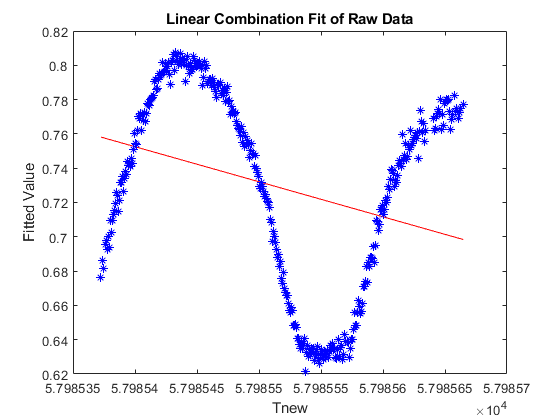

%plot
yfit =  c(1).*F1(Tnew) +  c(2).*F2(Tnew)  +  c(3).*F3(Tnew) ;
plot(Tnew,yfit,'r',KICB.Time,KICB.Flux,'*b')
title('Linear Combination Fit of Raw Data')
xlabel('Tnew')
ylabel('Fitted Value')

Poor guess. There is a clear periodicity so attempting periodic functions should help.

### Guess 2: Periodic functions from Gilat with original data

F1 =  @(x) x./x;
F2 =  @(x) cos(2*pi*(594.0864).*x);       
F3 =  @(x) sin(2*pi*(594.0864).*x);


%call the NLfit function
c = NLfit(F1,F2,F3,KICB.Time,KICB.Flux)

c =     0.7290
   -0.0003
   -0.0013


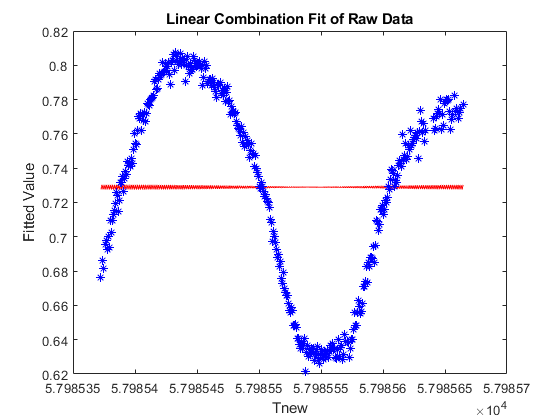

%plot
yfit =  c(1).*F1(Tnew) +  c(2).*F2(Tnew)  +  c(3).*F3(Tnew) ;
plot(Tnew,yfit,'r',KICB.Time,KICB.Flux,'*b')
title('Linear Combination Fit of Raw Data')
xlabel('Tnew')
ylabel('Fitted Value')

The period is too small so the factor $2\pi \;f$ is too large. A smaller guess is necessary.

### Guess 3: Adjusted Gilat periodic functions in seconds and interpolated

F1 =  @(x) x./x;
F2 =  @(x) cos(0.006876/(6*pi).*x);       
F3 =  @(x) sin(0.006876/(6*pi)*(x));


%call the NLfit function

c = NLfit(F1,F2,F3,Tnews,Mnew)

c =     0.7201
   -0.0718
    0.0294


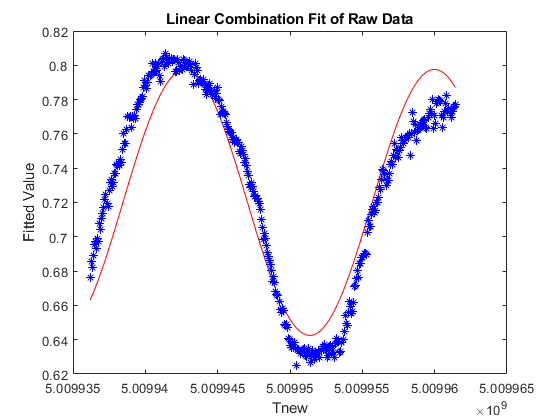

%plot

yfit =  c(1).*F1(Tnews) +  c(2).*F2(Tnews)  +  c(3).*F3(Tnews) ;
plot(Tnews,yfit,'r',Tnews,Mnew,'*b')
title('Linear Combination Fit of Raw Data')
xlabel('Tnew')
ylabel('Fitted Value')

This is a good fit but the question is why these functions and what the factor means.

### Guess 4: Another hypothesis similar to Guess 3

F1 =  @(x) x./x;
F2 =  @(x) cos(0.006876/(2*pi^2).*x);       
F3 =  @(x) sin(0.006876/(2*pi^2)*(x));


%call the NLfit function

c = NLfit(F1,F2,F3,Tnews,Mnew)

c =     0.7202
    0.0435
    0.0672


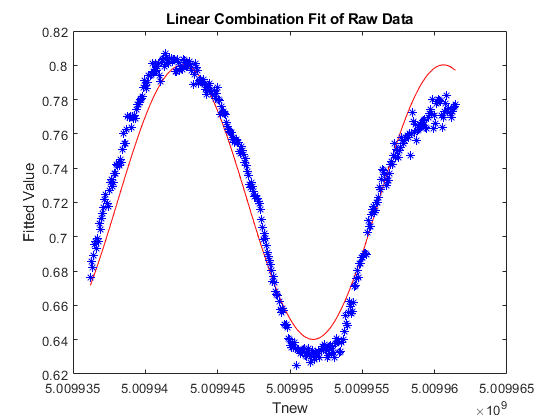

%plot

yfit =  c(1).*F1(Tnews) +  c(2).*F2(Tnews)  +  c(3).*F3(Tnews) ;
plot(Tnews,yfit,'r',Tnews,Mnew,'*b')
title('Linear Combination Fit of Raw Data')
xlabel('Tnew')
ylabel('Fitted Value')

This is fit looks visually better than guess 3.

## Chi-squared

%use guess 4
F1 =  @(x) x./x;
F2 =  @(x) cos(0.006876/(2*pi^2).*x);       
F3 =  @(x) sin(0.006876/(2*pi^2)*(x));
c = NLfit(F1,F2,F3,Tnews,Mnew)

c =     0.7202
    0.0435
    0.0672


yfit = @(c,x) c(1).*F1(x) +  c(2).*F2(x)  +  c(3).*F3(x);
Options.ErrorsUnknown = 1;
[params,dParams,gof,stddev] = fitChiSquare(Tnews,Mnew,yfit,c,[],[],Options)

Fitting function parameters...

Local minimum possible.
lsqnonlin stopped because the size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>
Finding parameter 1 lower bound
Finding parameter 1 upper bound
Finding parameter 2 lower bound
Finding parameter 2 upper bound
Finding parameter 3 lower bound
Finding parameter 3 upper bound
Parameter 1 = 0.720202 + 0.000727965 - 0.000828687
Parameter 2 = 0.0434609 + 0.00113562 - 0.00113562
Parameter 3 = 0.067218 + 0.00115737 - 0.00115737
Reduced chi-square = 1.000000


params =     0.7202
    0.0435
    0.0672


dParams = 1×3 struct array with fields:
    dl
    lVal
    du
    uVal
    d


gof = struct with fields:
        chi2: 346.0000
         dof: 346
        eta2: 0.9333
    probChi2: 0.5101


stddev =     0.0148
    0.0148
    0.0148
    0.0148
    0.0148
    0.0148
    0.0148
    0.0148
    0.0148
    0.0148


%use guess 3
F1 =  @(x) x./x;
F2 =  @(x) cos(0.006876/(6*pi).*x);       
F3 =  @(x) sin(0.006876/(6*pi)*(x));
c = NLfit(F1,F2,F3,Tnews,Mnew)

c =     0.7201
   -0.0718
    0.0294


yfit = @(c,x) c(1).*F1(x) +  c(2).*F2(x)  +  c(3).*F3(x);
Options.ErrorsUnknown = 1;
[params,dParams,gof,stddev] = fitChiSquare(Tnews,Mnew,yfit,c,[],[],Options)

Fitting function parameters...

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>
Finding parameter 1 lower bound
Finding parameter 1 upper bound
Finding parameter 2 lower bound
Finding parameter 2 upper bound
Finding parameter 3 lower bound
Finding parameter 3 upper bound
Parameter 1 = 0.720055 + 0.00108043 - 0.00107076
Parameter 2 = -0.0717583 + 0.00146135 - 0.00146135
Parameter 3 = 0.0293649 + 0.00149639 - 0.00149639
Reduced chi-square = 1.000000


params =     0.7201
   -0.0718
    0.0294


dParams = 1×3 struct array with fields:
    dl
    lVal
    du
    uVal
    d


gof = struct with fields:
        chi2: 346.0000
         dof: 346
        eta2: 0.8890
    probChi2: 0.5101


stddev =     0.0191
    0.0191
    0.0191
    0.0191
    0.0191
    0.0191
    0.0191
    0.0191
    0.0191
    0.0191


eta is better for guess 4 and 0.933 is a very good fit. Else guess 3 and 4 are similar.

## Important functions


function [Tnew,Mnew] = Interp_Lin(T,M)
%Interp_Lin user-defined linear interpolstion function
%
%   Usage:
%   [Tnew,Mnew] = Interp_nearest(T,M)
%       Uses data and y=mx+b to interpolate.
%
%   Author:     J. Evans
%   Updated:    11/29/2021
%
%   Inputs:
%       T   - A length m vector of independent variable data (time)
%       M   - A length m vector of dependent variable data (flux)
%
%   Outputs:
%       Tnew    - A length m vector of independent variable data (time at
%       regular intervals)
%       Mnew    - A length m vector of dependent variable data (interpolated flux)
%       
%
%   Example:
%   Enclosed in live script.
%
%   Notes:
%   N/A
%
%   References:
%   N/A
%_________________________________________________________________________________

% --Sum all of the time differences between measurements--
n = numel(T);
sum = 0;
for l = 1:n-1
    sum = sum + abs(T(l+1) - T(l));
end

% --Find averaged time scale--
avg_dT = sum / (n-1);
Tnew = T(1):avg_dT:T(n);

% --Calculate Mnew values--
m = numel(Tnew);
Mnew = zeros(1,m);
Mnew(1) = M(1);
Mnew(m) = M(n);

for l = 2:m-1
    for k = 1:n
        if T(k) <= Tnew(l)
            if Tnew(l) <= T(k+1)
                Mnew(l) = (M(k+1) - M(k))./(T(k+1) - T(k)).*(Tnew(l)-T(k)) + M(k);
                %eq for a line. i.e. y = mx + b
            end
        end
    end
end
end

function [Tnew,Mnew] = Interp_nearest(T,M)
%Interp_nearest uses the built-in function 'interp1' with method 'nearest'
%
%   Usage:
%   [Tnew,Mnew] = Interp_nearest(T,M)
%       Uses data and built in functions to interpolate.
%
%   Author:     J. Evans
%   Updated:    11/29/2021
%
%   Inputs:
%       T   - A length m vector of independent variable data (time)
%       M   - A length m vector of dependent variable data (flux)
%
%   Outputs:
%       Tnew    - A length m vector of independent variable data (time at
%       regular intervals)
%       Mnew    - A length m vector of dependent variable data (interpolated flux)
%       
%
%   Example:
%   Enclosed in live script.
%
%   Notes:
%   N/A
%
%   References:
%   N/A
%_________________________________________________________________________________

% --Sum all of the time differences between measurements--
n = numel(T);
sum = 0;
for l = 1:n-1
    sum = sum + abs(T(l+1) - T(l));
end

% --Find averaged time scale--
avg_dT = sum / (n-1);
Tnew = T(1):avg_dT:T(n);

% --Calculate Mnew values--
Mnew = interp1(T,M,Tnew,'nearest');
end

function [Tnew,Mnew] = Interp_linear(T,M)
%Interp_linear uses the built-in function 'interp1' with method 'linear'
%
%   Usage:
%   [Tnew,Mnew] = Interp_linear(T,M)
%       Uses data and built in functions to interpolate.
%
%   Author:     J. Evans
%   Updated:    11/29/2021
%
%   Inputs:
%       T   - A length m vector of independent variable data (time)
%       M   - A length m vector of dependent variable data (flux)
%
%   Outputs:
%       Tnew    - A length m vector of independent variable data (time at
%       regular intervals)
%       Mnew    - A length m vector of dependent variable data (interpolated flux)
%       
%
%   Example:
%   Enclosed in live script.
%
%   Notes:
%   N/A
%
%   References:
%   N/A
%_________________________________________________________________________________

% --Sum all of the time differences between measurements--
n = numel(T);
sum = 0;
for l = 1:n-1
    sum = sum + abs(T(l+1) - T(l));
end

% --Find averaged time scale--
avg_dT = sum / (n-1);
Tnew = T(1):avg_dT:T(n);

%--Calculate Mnew values--
Mnew = interp1(T,M,Tnew,'linear');
end

function [Tnew,Mnew] = Interp_spline(T,M)
%Interp_spline uses the built-in function 'interp1' with method 'spline'
%
%   Usage:
%   [Tnew,Mnew] = Interp_spline(T,M)
%       Uses data and built in functions to interpolate.
%
%   Author:     J. Evans
%   Updated:    11/29/2021
%
%   Inputs:
%       T   - A length m vector of independent variable data (time)
%       M   - A length m vector of dependent variable data (flux)
%
%   Outputs:
%       Tnew    - A length m vector of independent variable data (time at
%       regular intervals)
%       Mnew    - A length m vector of dependent variable data (interpolated flux)
%       
%
%   Example:
%   Enclosed in live script.
%
%   Notes:
%   N/A
%
%   References:
%   N/A
%_________________________________________________________________________________



% --Sum all of the time differences between measurements--
n = numel(T);
sum = 0;
for l = 1:n-1
    sum = sum + abs(T(l+1) - T(l));
end

% --Find averaged time scale--
avg_dT = sum / (n-1);
Tnew = T(1):avg_dT:T(n);

% --Calculate Mnew values--
Mnew = interp1(T,M,Tnew,'spline');
end

function [Tnew,Mnew] = Interp_polyfit(T,M)
%Interp_polyfit uses the built-in function 'interp1' with method 'polyfit'
%
%   Usage:
%   [Tnew,Mnew] = Interp_polyfit(T,M)
%       Uses data and built in functions to interpolate.
%
%   Author:     J. Evans
%   Updated:    11/29/2021
%
%   Inputs:
%       T   - A length m vector of independent variable data (time)
%       M   - A length m vector of dependent variable data (flux)
%
%   Outputs:
%       Tnew    - A length m vector of independent variable data (time at
%       regular intervals)
%       Mnew    - A length m vector of dependent variable data (interpolated flux)
%       
%
%   Example:
%   Enclosed in live script.
%
%   Notes:
%   N/A
%
%   References:
%   N/A
%_________________________________________________________________________________

% --Sum all of the time differences between measurements--
n = numel(T);
sum = 0;
for l = 1:n-1
    sum = sum + abs(T(l+1) - T(l));
end

% --Find averaged time scale--
avg_dT = sum / (n-1);
Tnew = T(1):avg_dT:T(n);

% --Calculate Mnew values--
n = numel(T);
p = polyfit(T,M,5);
Mnew = polyval(p,Tnew);
end



function [fk,powerNor] = EnergySpec(t,f,dt)
%EnergySpec Performs a fourier transform and plots a shifted power spectrum.
%
%   Usage:
%   [fk,powerNor] = EnergySpec(t,f,dt)
%       Uses data and built in functions to plot Power Spectrum.
%
%   Author:     J. Evans
%   Updated:    11/29/2021
%
%   Inputs:
%       t   - A length m vector of independent variable data (time)
%       f   - A length m vector of dependent variable data (flux)
%       dt  - A scalar value of the difference between values of t
%
%   Outputs:
%       fk          - resulting frequencies
%       powerNor    - resulting normalised power spectrum
%       
%
%   Example:
%   Enclosed in live script.
%
%   Notes:
%   N/A
%
%   References:
%   1. this function is developed with refeernce to Gilat Program 7-4 and Example 7-6
%_________________________________________________________________________________


N = length(f);
F = fft(f)/N;
F0 = fftshift(F);

power = F0.*conj(F0)/N;
powerNor = power/max(power);

%Plot power Spectrum
fs = 1/dt;
fk = (0:N-1)*(fs/N);

plot(fk, powerNor)
xlabel('frequency (Hz)')
ylabel('normalized power')
end

function C = NLfit(F1,F2,F3,x,y)
%NLfit Performs a fit on a linear combination of nonlinear functions.
%
%   Usage:
%   C = NLfit(F1,F2,F3,x,y)
%       Uses matrix operations and given functions to model the x and y
%       data.
%
%   Author:     J. Evans
%   Updated:    11/29/2021
%
%   Inputs:
%       F1  - A modeling function guess (anonymous function):
%       F2  - A modeling function guess (anonymous function):
%       F3  - A modeling function guess (anonymous function):
%       x   - A length m vector of independent variable data.
%       y   - A length m vector of dependent variable data.
%
%
%   Outputs:
%       C  - a length 3 vector of fit model parameters
%       
%
%   Example:
%   Enclosed in live script.
%
%   Notes:
%   N/A
%
%   References:
%   1. Gilat example 6-9
%_________________________________________________________________________________

F1 = F1(x);
F2 = F2(x);
F3 = F3(x);

A(1,1) = sum(F1 .* F1);
A(1,2) = sum(F1 .* F2);
A(1,3) = sum(F1 .* F3);
A(2,2) = sum(F2 .* F2);
A(2,3) = sum(F2 .* F3);
A(3,3) = sum(F3 .* F3);

A(2,1) = A(1,2);    % A is symmetric
A(3,1) = A(1,3);
A(3,2) = A(2,3);

B(1,1) = sum(y .* F1);
B(2,1) = sum(y .* F2);
B(3,1) = sum(y .* F3);

%form is A*C=B, Therefore,

C = A\B;

end



Chisquared function from mathworks site

function [params,dParams,gof,stddev]...
    = fitChiSquare(xData,yData,modelFun,guess,dxData,dyData,options)
%FITCHISQUARE Performs a chi-square fit returning parameter uncertainty.
%
%   Usage:
%
%   [params,dParams,gof,stddev] =
%       fitChiSquare(xData,yData,modelFun,guess,dxData,dyData)
%
%       Performs a least-squares fit of the parameters of modelFun,
%       minimizing the chi-square between the model and the data, using the
%       specified uncertainties in x and y data.
%
%   ... = fitChiSquare(xData,yData,modelFun,guess,dxData,dyData,options)
%
%       As above, with the specified options.
%
%   ... = fitChiSquare(xData,yData,modelFun,guess)
%
%       Uses empty data uncertainty arrays, sets ErrorsUnknown to true.
%
%   Author:     N. Brahms
%   Contact:    Contact via Matlab File Exchange website
%   Version:    2.5
%   Updated:    5/26/06
%
%   Inputs:
%       xData   - A m x n matrix of independent variable data, where
%                   columns represent independent variables, and rows
%                   represent successive observations thereof.
%       yData   - A length m vector of dependent variable data.
%       dxData  - A m x n matrix of uncertainties corresponding to each
%                   measurement in xData.  May be [] if
%                   Options.ErrorsUnknown = 1.
%       dyData  - A length m vector of uncertainties corresponding to each
%                   measurement in yData.  May be [] blank if
%                   Options.ErrorsUnknown = 1.
%       modelFun- A pointer to a vectorized modeling function:
%
%           [result] = modelFun(params,xData)
%
%           which returns a length m vector of f(x) using the parameters
%           passed.
%
%       guess   - A length k vector of initial guesses for the parameters.
%       options - An options struct to pass to the fitting routine;
%                 this is the same as described in optimset, but with the
%                 following additional fields.  If any of the following
%                 fields are absent from the struct, the default value is
%                 used.  This parameter is optional.
%
%           Display = 'iter' | {'on'} | 'off'
%               Passed to the fitting routine.  If set to 'on' or 'iter',
%               also causes fitChiSquare to display the fitting results in
%               the command window.
%           Plot = {0} | 1
%               Plots the fit result.  If PlotResiduals is also on, the fit
%               result is plotted in subplot [1 2] and the residuals are
%               plotted in subplot 3.
%           PlotVariable = {1} | ... | k
%               Which independent variable to plot against.
%           PlotResiduals = {0} | 1
%               Plots the weighted fit residuals
%           ErrorsUnknown = {0} | 1
%               Set this option to 1 if data uncertainties (dxData or dyData)
%               are unknown. fitChiSquare produces an error if
%               ErrorsUnknown is 0 and either dxData or dyData is empty.
%               If 0, then
%                   chi2 may be interpretred as a statistic indicating the
%                   likelihood that the model is appropriate for describing
%                   the observed data.  See definitions of chi2 and
%                   probChi2 above.  The delta chi2 = 1 bounds (dParams.dl
%                   and dParams.du) may be interpreted as 68% confidence
%                   intervals for the parameters (given that the parameters
%                   are gaussian-distributed).  stddev is given by
%                       stddev = sqrt(dy^2 + sum( (df/dxi*dxi)^2 ) )
%                   where dy and dxi are the data uncertainties and df/dxi
%                   is the finite-difference derivative of the model versus xi.
%               If 1, then
%                   chi2 is set to 1, and neither chi2 nor probChi2 carry
%                   meaning.  The delta chi2 = 1 bounds may be interpreted
%                   as "68% confidence intervals for the parameters given
%                   the model is correct."
%
%               If 1, assumes the model is correct (that is, chi2 is set to 1)
%               and uses the model to calculate the data standard deviation.
%               Assumes standard deviation is uniform by datum.
%               If using ErrorsUnknown, the delta chi2 = 1 bounds for the
%               parameters can only be interpreted as the "68%
%               confidence interval given the model is correct" (and then
%               only if the parameters are gaussian-distributed).
%               If 0, uses measurement errors to calculate the data
%               standard deviation.  Chi2 is a meaningful estimate of model
%               accuracy.  The delta chi2 = 1 bounds may be interpreted as
%               the "68% confidence interval" (if the parameters are
%               gaussian-distributed).
%           FitUncertainty = 0 | {1} | k-vector
%               If 1 (default), fits uncertainties
%               If 0, does not fit uncertainties (returns empty dparams)
%               If length k boolean vector, fits uncertainties only to 'on'
%                 indices.  Example for a three parameter fit:
%                   FitUncertianty = [0 1 1];
%           FitIndex = {ones(size(guess))} | k-vector
%               fitChiSquare only fits each parameter if the corresponding
%               index in FitIndex is true.
%           LowerBound     = vector | {[-Inf ... -Inf]}
%               a length k row vector of parameter lower bounds
%           UpperBound     = vector | {[Inf ... Inf]}
%               a length k row vector of parameter upper bounds
%           DisplayUncVal  = {0} | 1
%               shows additional information when fitting the uncertainties
%           MaxUncIter = {10}
%               maximum number of iterations in uncertainty solver
%           MaxUncCount = {20}
%               maximum number of function calls in uncertainty solver
%           UncOptions  = optimset options |
%                            {optimset('TolFun',1e-2,'Display','off')}
%               optimset options to pass to uncertainty solver (fzero)
%           Scale = {0} | 1
%               If 1, uses parameter scaling to make optimization radix
%               equally sensitive to each parameter.  This is useful if
%               parameters take on values different by more than an order
%               of magnitude (i.e. p = [1 1e10]).  Note that the scaling
%               factor is determined from the guess, so zero guesses are
%               not scaled.
%
%   Outputs:
%       params  - a length k vector of fit model parameters
%       dParams - a length k cell array of structures with the following
%                 fields:
%           d   - equals (dl+du)/2
%           dl  - absolute lower deviation at dChi^2=1 of the indexed
%                 parameter
%           du  - absolute upper deviation at dChi^2=1 of the indexed
%                 parameter
%           lVal- a length k vector of the value of each parameter at the
%                 dChi^2=1 projection point for the lower deviation of the
%                 indexed paramter
%           uVal- a length k vector of the value of each parameter at the
%                 dChi^2=1 projection point for the upper deviation of the
%                 indexed parameter
%       gof     - a goodness-of-fit struct with the following fields:
%           chi2- the chi-square of the fit
%           dof - degrees-of-freedom of the fit
%           eta2- the eta-square of the fit (a.k.a. correlation index) -
%                 this quantity is analogous to the r-square (correlation
%                 coefficient) of a linear least-squares fitting [3]
%           probChi2 - the probability of obtaining a chi-square equal to or
%                      greater than chi2 given the data is drawn from the
%                      model using the best-fit parameters
%       stddev  - the expected deviation from the fit for each observation
%
%   Example:
%   Run and edit fitChiSquareExample for example use.
%
%   Notes:
%   fitChiSquare is a generalized chi-square fitting routine for any
%   model function when data measurement errors are known; it returns the
%   model parameters and their uncertainties at the delta chi-squared = 1
%   boundary (68% confidence interval).  Alternatively, it can be used to
%   determine measurement errors when the theoretical function is known.
%
%   This function uses the optimization toolbox function lsqnonlin to first
%   perform a nonlinear least squares fit of the data to the model.  It
%   then calculates the standard deviation of each point to the fit value,
%   then calculates the chi squared.  Finally, the function fzero is
%   used on each parameter to find the value at which delta chi-squared is
%   equal to 1 while minimizing chi^2 with respect to the other parameters.
%   In the case that the parameter uncertainties are normally distributed,
%   the delta chi^2 = 1 method gives the 68% confidence limit for the
%   parameters.  Monte Carlo or investigations of many data sets should be
%   used to confirm the parameter uncertainties are normally distributed.
%   This method gives upper and lower bounds for each parameter.[1,2]
%
%   If one encounters the following error message:
%
%       Unexpected termination flag 0 in non-estimating variable
%       minimization during uncertainty estimation
%
%   this is because the non-varying parameter minimization routine has
%   encountered its iteration or evaluation limit.  Raise
%   options.UncOptions.MaxFunEvals or options.UncOptions.MaxIter.
%
%   Note:  If the user can not use lsqnonlin (i.e., the optimization
%   toolbox is not installed), the program will use the built-in function
%   fminsearch instead.  This may reduce the robustness and/or speed of
%   the calculation.
%
%   References:
%   1. W.H. Press, B.P. Flannery, S.A. Teukolsky, W.T. Vetterling.
%      Numerical Recipes; The Art of Scientific Computing. (Cambridge
%      University Press: Cambridge). 1986.
%   2. P.R. Bevington, D.K. Robinson. Data Reduction and Error Analysis
%      for the Physical Sciences. (McGraw-Hill: New York). 1992.
%   3. http://mathworld.wolfram.com
%--------------------------------------------------------------------------
%   (c) 2006 N. Brahms
%
%   History
%       1.0     - Initial version
%       1.1     - Changed syntax and added the doError switch
%       1.1.1   - Added more detailed reporting
%       1.2     - Changed parameter uncertainty minimization function from
%                 fminbnd to fminsearch with coded constraints
%       1.3     - Changed non-estimating parameter minimization to occur
%                 inside fminsearch in uncertainty minimization.  Also,
%                 fixed a bug causing improper weighting of initial chi2
%                 minimization.  Removed doError switch.
%       1.3.1   - Minor code rearrangement
%       1.3.2   - Can run without the optimization toolbox
%       1.3.3   - Added UncMaxFunEvals & UncMaxIter options
%       1.3.4   - Fixed a bug whereby the uncertainty estimator would
%                 return bogus values instead of an error if the included
%                 non-varying parameter minimization routine halted
%                 unexpectedly.
%       2.0     - File name change to fitChiSquare.  Added example use
%                 file and included between function in release.  Added
%                 stddev output.
%       2.1     - Added bounds, uncertainty options.  Updated
%                 documentation.
%       2.2     - Added ErrorsUnknown option, cleaned up documentation.
%       2.3     - Added plotting options, changed to allow FitUncertainty
%                 with ErrorsUnknown. Changed dParams to normal array.
%       2.4     - Added gof struct - note syntax change
%       2.4.1   - Fixed bug where struct was misassigned if
%                 FitUncertainty(1) was equal to 0
%       2.4.2   - Added probchi2 field to gof struct
%       2.4.3   - M-Lint optimization
%       2.4.4   - Changed options handling to make code cleaner, added
%                 ability to fit only a variable subspace
%       2.5     - Added Scale option
%       2.5.1   - Help updates, options is now optional :)
%       2.6     - Added 4 parameter syntax
%
%   Known problems / suggested features
%       - Add flags indicating that the fit has stopped at bounds
%
%--------------------------------------------------------------------------
% Uncertainty loop constants and defaults
LARGE_NUM = realmax;    % The number used in the minimization routine when
                        % the minimizing variable is out of bounds
if ~exist('options','var')
    options = optimset;
end
options = initializeOptions(options,guess);
opEPar = initializeUncOptions(options);
if nargin==4
    options.ErrorsUnknown = true;
    dxData = [];
    dyData = [];
end
% Check degrees of freedom
if (length(yData) <= length(guess))
    error('Nonpositive degrees of freedom');
end
% Condition input
[xData, dxData, yData, dyData] = conditionInput(xData, dxData,...
    yData, dyData, ~options.ErrorsUnknown);
% Force bound vectors to be row vectors
options.LowerBound = conditionBound(options.LowerBound);
options.UpperBound = conditionBound(options.UpperBound);
% Scale input for unit radix
scale = ones(size(guess));
if options.Scale
    scale(guess~=0) = abs(guess(guess~=0));
    guess = guess./scale;
    if ~isempty(options.OutputFcn)
        unscaledOutputFcn = options.OutputFcn;
        options.OutputFcn = @(p,ov,s) feval(unscaledOutputFcn,p*scale,ov,s);
    end
end
% Check guess is in bounds
for ia=1:length(guess)
    if any(options.LowerBound>options.UpperBound)
        error('Lower bound exceeds upper bound')
    end
    if ~between(guess(ia)*scale(ia),[options.LowerBound(ia) options.UpperBound(ia)],1)
        error('Guess %d is not in bound',ia);
    end
end
% Nested function variable initialization
pVarIndex = 0;
pVar      = 0;
pFix      = 0;
pEVarVal  = zeros(length(guess)-1,1);
pEVarInd  = zeros(length(guess)-1,1);
pVarBnd   = [-Inf, Inf];
pVarMult  = 1;
if ~strcmp(options.Display,'off')
    disp('Fitting function parameters...');
end
% Calculate the degrees of freedom of the problem
dof = length(yData)-length(guess);
% Calculate the fit with uniform uncertainty
stddev = 1;
% Average deviation from the guess
stddev = sqrt(sum(model(guess).^2)/dof);
if ~options.ErrorsUnknown
    startOptions = options; startOptions.TolFun = 1e-2; startOptions.TolX = 1e-8;
    params = trylsq(@model,guess,[],[],startOptions);
    % Calculate the standard deviation for each datum
    stddev = calcStdDev;
    % Calculate the least-squares fit
    params = trylsq(@model,params,[],[],options);
else
    % Calculate the least-squares fit
    params = trylsq(@model,guess,[],[],options);
    stddev = 1;
    stddev = sqrt(sum(model(params).^2)/dof)*ones(length(yData),1);
end
% Calculate the chi-square function
chiSquare = sum( model(params).^2 );
% Fill goodness-of-fit struct
gof.chi2 = chiSquare;
gof.dof  = dof;
gof.eta2 = (std( (yData-model(params).*stddev) ) / std( yData) )^2;
gof.probChi2 = chi2prob(chiSquare,dof);
% Fits parameter uncertainties
% Be careful not to use ia in any nested functions!
dParams = initializeDParams;
dParams(1:length(params)) = dParams;
for ia=1:length(params)
    if options.FitUncertainty(ia)
        dParams(ia)=delta(ia);
    end
end
% Rescale data back from unity
params = params.*scale;
for ia=1:length(dParams)
    dParams(ia).du = dParams(ia).du*scale(ia);
    dParams(ia).dl = dParams(ia).dl*scale(ia);
    dParams(ia).d  = dParams(ia).d*scale(ia);
    dParams(ia).lVal = dParams(ia).lVal*scale(ia);
    dParams(ia).uVal = dParams(ia).uVal*scale(ia);
end
% If a verbose mode is on, display the answer and reduced chi-squared
if ~strcmp(options.Display,'off')
    for id=1:length(params)
        disp(sprintf('Parameter %d = %g + %g - %g',...
            id,params(id),dParams(id).du,dParams(id).dl));
    end
    disp(sprintf('Reduced chi-square = %f',chiSquare/dof));
end
% Plot the fit
if options.Plot
    % Subplot if also plotting residuals
    if options.PlotResiduals
        subplot(3,1,[1 2]);
    end
    holdstate = ishold;
    errorbar(xData(:,options.PlotVariable),yData,stddev,'.');
    plotHandle = gca;
    hold on
    plot(xData(:,options.PlotVariable),...
        yData - model(params./scale).*stddev,'-r');
    switch holdstate
        case 0
            hold off
    end
    xlabel('x1');
    ylabel('y');
    title('Fit plot');
    lstring = sprintf('Fit: ~\\chi^2 = %0.2g\n',chiSquare/dof);
    for ia = 1:length(params);
        lstring = [lstring ...
            sprintf('Par. %d = %0.2g + %0.1g - %0.1g\n',...
            ia,params(ia),dParams(ia).du,dParams(ia).dl)];
    end
    legend({sprintf('Data \\pm \\sigma'),lstring(1:end-1)});
        
end
% Plots the weighted fit residual
if options.PlotResiduals
    if options.Plot
        subplot(3,1,3);
    end
    holdstate = ishold;
    plot(xData(:,options.PlotVariable),model(params./scale),'.');
    hold on
    line([min(xData(:,options.PlotVariable)) max(xData(:,options.PlotVariable))],...
        [0 0],'Color',[1 0 0]);
    switch holdstate
        case 0
            hold off
    end
    xlabel('x1');
    ylabel('Residual');
    title('Weighted residual plot');
    if options.Plot
        set(gca,'XLim',get(plotHandle,'XLim'));
    end
end
if options.Plot || options.PlotResiduals
    drawnow
end
% Last executing line of fitChiSquare    
% --- Internal functions follow ------------------------------------------
    % ----------- model --------------------------------------------------
    % This calls the model function.  It returns the residual at each
    % datum.
    function F = model(x)
        
        % If we scaled to unit radix, we must scale back before calling the
        % model.  Since scale was initialized to ones, we just multiply in
        % any case.
        x = x.*scale;
        
        % Handle boundary
        testInBound = between(x,[options.LowerBound; options.UpperBound],1);
        
        if ~all(testInBound)
            % Return ridiculously large number
            F = sqrt(LARGE_NUM)/(length(x)+1)*ones(length(xData),1);
        else
            % Return the chi-value
            F = (yData - feval(modelFun,x,xData))./(stddev+eps); 
            %eps to avoid problems with zero weights
        end
    end
    % ----------- modelError ---------------------------------------------
    % Used in finding the point-by-point standard deviation
    function F = modelError(x,xbndData)   
        % See model
        x = x.*scale;
        
        F = feval(modelFun,x,xbndData);
    end
    % ---------- calcStdDev ------------------------------------------------
    % Calculates the std. dev. of (f(x_i)-y_i) using finite methods
    function sigma = calcStdDev
        dim = size(xData);
        dm2 = zeros(dim(1),1);
        for ib=1:dim(2)
            xtestu = xData;
            xtestl = xData;
            xtestu(:,ib) = xtestu(:,ib)+dxData(:,ib);
            xtestl(:,ib) = xtestl(:,ib)-dxData(:,ib);
            dmodelu = modelError(params,xtestu);
            dmodell = modelError(params,xtestl);
            dm2 = dm2 + (dmodelu-dmodell).^2/4;
        end
        sigma = sqrt(dyData.^2+dm2);
    end
    %-------------------- fzeroOutput ---------------------------
    % Used with fzero to stop when UncIter is exceeded
    function stop = fzeroOutput(x,o)
        
        if o.iteration > options.MaxUncIter || o.funccount > options.MaxUncCount
            stop = 1;
        else
            stop = 0;
        end
            
        % Display iterative function information
        if options.DisplayUncVal
            str1 = sprintf('Iteration = %d\tVarA = %6.4g\tVarB = %6.4g\tFValA = %6.4g\tFValB = %6.4g\tEVal = ',...
                o.iteration,o.intervala,o.intervalb,o.fvala,o.fvalb);
            str2 = sprintf('%g\t',pEVarVal);
            disp([str1 str2]);
        end
        
    end
    %----------------------- modelFix ---------------------------
    % This function is used to fit only one variable to delta chi2 = 1.  It
    % is used with fzero, not lsqnonlin.
    function F = modelFix(var)
        
        if between(var,pVarBnd,1)
            
            pVar = var;
            if length(params)>1
                [pEVarVal,eflag] = trylsq(@modelNFix,pEVarVal,[],[],opEPar);
                if(eflag<=0)
                    disp(sprintf(['\tUnexpected termination flag %d in'...
                        ' non-estimating variable minimization\n\tduring'...
                        ' uncertainty estimation'],eflag));
                    F=NaN;
                else
                    x = reconstruct(pVar);
                    F = (chiSquare+1) - sum( model(x).^2 );
                end
            else
                F = (chiSquare+1) - sum( model(var).^2 );
            end
            
        % If past the variable-side bound, make F large.  If past the
        % extent-side bound, make F infinitely negative.
        elseif var<min(pVarBnd)
            F = pVarMult*LARGE_NUM;
            eflag = 1;            
        elseif var>max(pVarBnd)
            F = -pVarMult*LARGE_NUM;
            eflag = 1;
        end
    end % modelFix
    % ------------ reconstruct -------------------------------------------
    % Builds the parameter array from pEVar and pVar
    function x = reconstruct(in)
        x = zeros(size(params));
        for ic=1:length(pEVarInd)
           x(pEVarInd(ic)) = pEVarVal(ic);
        end
        x(pVarIndex) = in;
    end
    % ------------ modelNFix ---------------------------------------------
    % This function is used to fit all but one variable
    function F = modelNFix(x)
        xu = zeros(size(params));
        for ig=1:length(pEVarInd)
            xu(pEVarInd(ig)) = x(ig);
        end
        xu(pVarIndex) = pVar;
        F = model(xu);
    end
    % ------------ delta -------------------------------------------------
    % This function finds the variation to delta chi-squared = 1
    % One variable minimizes chi-square+1, while the other variables minimize
    % chi-squared
    function bnd = delta(varyingIndex)
        
        bnd = initializeDParams;
        
        % These are the shared variables for the fitting functions
        pVarIndex = varyingIndex;   % The index of the variable being solved
        
        j=1;                        % Load all the other variables in an array
        for ie=1:length(params)
            if ie~=varyingIndex
                pEVarVal(j)=params(ie);
                pEVarInd(j)=ie;
                j=j+1;
            end
        end
        pEVarValStatic = pEVarVal;  % The non-varying initial array value
        
        pVar = params(pVarIndex);   % The solution is stored here, but must
                                    % start at the minimized value
        
        % This is the original variable value
        pFix = params(pVarIndex);
        
        if ~strcmp(options.Display,'off')
            disp(sprintf('Finding parameter %d lower bound',varyingIndex));
        end
        % Calculate the lower bound
        [bnd.dl,bnd.lVal] = uncMin('lb');
        bnd.dl = pFix-bnd.dl;
        
        % Here we have to reinitiate the variables
        pEVarVal = pEVarValStatic;
        pVar = params(pVarIndex);
        
        % Calculate the upper bound
        if ~strcmp(options.Display,'off')
            disp(sprintf('Finding parameter %d upper bound',varyingIndex));
        end
        
        [bnd.du,bnd.uVal] = uncMin('ub');
        bnd.du = bnd.du-pFix;
        
        bnd.d = mean([bnd.du bnd.dl]);
        
        % This function finds the parameter deviation for delta chi-squared
        % = 1, and then reminimizes the other variables.
        function [bnd,val] = uncMin(lbub)
            
            % Set the search bounds on the uncertainty
            switch(lbub)
                case 'ub'
                    pVarBnd = [pFix, options.UpperBound(varyingIndex)]; A=1;
                case 'lb'
                    pVarBnd = [options.LowerBound(varyingIndex), pFix]; A=-1;
            end
            pVarMult = A;
            
            opParDev = initializeUncOptions(options);
            opParDev.OutputFcn = @(x,o,s) fzeroOutput(x,o);
            % Find the parameter deviation to get delta chi2 = 1
%             [bnd,fval,exitflag] = fzero(@modelFix,pFix,opParDev);
            bnd = fzero(@modelFix,pFix,opParDev);
            
            % Assign the result
            val = reconstruct(bnd);
                
            if options.DisplayUncVal
                disp(sprintf('Fix = %g\tVar = %g\tChi2 = %g',...
                    pFix,pVar,chiSquare));
            end
        end % uncMin
    end % delta
end % fitChiSquare
% ----- initializeUncOptions ------------------------------------------
function uncOp = initializeUncOptions(options)
% Set a relatively high finishing tolerance
uncOp = options.UncOptions;
end %initializeUncOptions
    
% ----- initializeOptions ---------------------------------------------
function options = initializeOptions(optionsIn,guess)
% Manufacture the fit options defaults
options = optimset;
options.Plot = false;
options.PlotResiduals = false;
options.PlotVariable = true;
options.FitUncertainty = true(1,length(guess));
options.FitIndex = true(1,length(guess));
options.ErrorsUnknown = false(1,length(guess));
options.UncOptions=optimset('TolFun',1e-2,'Display','off');
options.DisplayUncVal=false;
options.LowerBound=-Inf*ones(1,length(guess));
options.UpperBound=Inf*ones(1,length(guess));
options.Scale = false;
options.MaxUncIter = 10;
options.MaxUncCount = 20;
names = fieldnames(options);
for i = 1:length(names)
    if isfield(optionsIn,names{i})
        if length(optionsIn.(names{i})) == 1 &&...
                length(options.(names{i})) == length(guess) &&...
                length(guess)>1
            optionsIn.(names{i}) = optionsIn.(names{i})*ones(1,length(guess));
        end
        if islogical(options.(names{i}))
            options.(names{i}) = convertBoolean(optionsIn.(names{i}));
        else
            options.(names{i}) = optionsIn.(names{i});
        end %if islogical
    end %if isfield
end %for
end
    
% ----- chi2fun ----------------------------------------------------------
% Returns the probability of chi-square equal to or greater than x, with r
% degrees of freedom.  This is 1-D(x,r), where D is the cumulative
% distribution function.  See
% http://mathworld.wolfram.com/Chi-SquaredDistribution.html
% Note that MATLAB's gammainc is the "regularized gamma function" used in
% MathWorld.
function p = chi2prob(x,r)
p = gammainc(r/2,x/2);
end
% ----- trylsq ------------------------------------------------------------
% Uses lsqnonlin if it exists
function [sol,exitflag] = trylsq(fun,x0,lb,ub,options)
    if(exist('lsqnonlin','file'))
        [sol,trash,trash,exitflag] = lsqnonlin(fun,x0,lb,ub,options);
    else
        [sol,trash,exitflag] = fminsearch(@modelChi2,x0,options);
    end 
    % For use when substituting fminsearch for lsqnonlin
    function F = modelChi2(x)
        F = sum(feval(fun,x).^2);
    end
end
% ----- between -----------------------------------------------------------
% Returns the portion of vector in and out of the range ( as determined by
% the inclusive tag )
function [inner,outer] = between(vector,range,inclusive)
    if ~exist('inclusive','var')
        inclusive = 0;
    end
    if inclusive
        inner = vector<=max(range) & vector>=min(range);
        outer = vector<=min(range) & vector>=max(range);
    else
        inner = vector<max(range) & vector>min(range);
        outer = vector<min(range) & vector>max(range);
    end
    
end
% ----- conditionInput ----------------------------------------------------
function [xData, dxData, yData, dyData] = conditionInput(xin, dxin, yin, dyin,...
    doError)
xData = xin; dxData = dxin; yData = yin; dyData = dyin;
% Force yData and dyData to be column vectors
siy = size(yData);
if siy(1)>1 && siy(2)>1
    error('Y is not a vector');
end
yData = yData(:);
siy = size(yData);
if doError
    sidy = size(dyData);
    if sidy(1)>1 && sidy(2)>1
        error('dY is not a vector');
    end
    dyData = dyData(:);
    sidy = size(yData);
end
% Transpose xData if it is n x m, not m x n
six = size(xData);
if (siy(1) == six(2) && siy(1) ~= six(1))
    xData = xData';
    six = size(xData);
end
if doError
    sidx = size(dxData);
    if (siy(1) == sidx(2) && siy(1) ~= sidx(1))
        dxData = dxData';
        sidx = size(dxData);
    end
end
% Check that vectors match
if (siy(1) ~= six(1))
    error('X and Y data vectors do not match.')
end
if doError
    % Grow error vectors if the user passed scalar errors
    if sidx(1) == 1 && sidx(2) == six(2)
        for i=1:six(2)
            dxData(2:length(xData(:,1)),i)=dxData(1,i);
        end
        sidx = size(dxData);
    end
    if sidy(1) == 1 && sidy(2) == 1
        dyData(2:length(yData(:,1)),1)=dyData(1);
        sidy = size(dyData);
    end
    if any((sidx ~= six) | (sidy ~= siy))
        error('Data vectors do not match error vectors');
    end
end
end
% ----- initializeDParams -------------------------------------------------
function dParamsEmpty = initializeDParams()
dParamsEmpty = struct('dl', NaN, 'lVal', [], 'du', NaN, 'uVal', [],...
    'd',NaN);
end
% ----- conditionBound ----------------------------------------------------
function boundVecOut = conditionBound(boundVecIn)
sib = size(boundVecIn);
if (sib(1)~=1 && sib(2)==1)
    boundVecOut = boundVecIn';
elseif (sib(1)~=1)
    error('Badly formed bound vector');
else
    boundVecOut = boundVecIn;
end
end
% ----- convertBoolean ----------------------------------------------------
% Converts vectors of {>0, <=0} or {'on', 'off'} to
% vectors of {1, 0}
function value = convertBoolean(in)
warning off MATLAB:sprintf:InputForPercentSIsNotOfClassChar;
errstr = ['Input vector' sprintf(' %s',in)...
            ' can not be converted to a boolean value'];
warning on MATLAB:sprintf:InputForPercentSIsNotOfClassChar;
% Handles cell arrays
if iscell(in)
    % All cells are numbers
    if all(isnumeric(cell2mat(in)))
        value = cell2mat(in) > 0;
    elseif islogical(cell2mat(in))
        value = cell2mat(in);
    % All cells are 'on' or not 'on'
    elseif iscellstr('in');
        in = lower(in);
        for i=1:length(in)
            switch in{i}
                case 'on'
                    value(i)=true;
                case 'off'
                    value(i)=false;
                otherwise
                    error(errstr);
            end %switch
        end %for
    else
        error(errstr);
    end %if number or string
% Array of numbers or booleans, or single string
else
    if all(isnumeric(in))
        value = in > 0;
    elseif all(islogical(in))
        value = in;
    elseif isa(in,'char') && all(isstrprop(in,'alpha'));
        switch lower(in)
            case 'on'
                value=true;
            case 'off'
                value=false;
            case 'true'
                value=true;
            case 'false'
                value=false;
            otherwise
                error(errstr);
        end %switch
    else
        error(errstr);
    end %if number or string
end %if cell
end %convertBoolean